# Design a Deep Neural Network with Simulated Data to WLAN Router Impersonator

RF 핑거프린팅을 위해 알려지거나 알려지지 않은 라우터의 시뮬레이션된 WLAN 비콘 프레임을 이용해 CNN을 교육한다.

그런 다음 **수신된 신호의 MAC 주소**와** CNN이 감지한 RF 지문**을 비교하여 WLAN 라우터 가장자를 감지한다.

## 1.   Set System Parameters

- Known Router의 label로 MAC 주소를 사용한다.

- 훈련 80 검증 10 테스트 10,  5G Hz 대역에서 작동하는 20dB SNR을 고려

numKnownRouters = 4;    % 알려진 장치 수
numUnknownRouters = 10; % 모르는 장치 수
% Unkwnown Router이 RF 지문의 변화를 관찰하기 위해 Known보다 많은 개수로 설정
 
 % 총 라우터 수
numTotalRouters = numKnownRouters+numUnknownRouters;   
SNR = 20;                 % dB
channelNumber = 153;      % WLAN 채널 번호
channelBand = 5;          % 5GHz 대역
frameLength = 160;        % L-LTF sequence length in samples



trainNow = false ;

if trainNow
    % 실험할 때, 생성할 non-HT WLAN 비콘 프래임 수
  numTotalFramesPerRouter = 5000; %#ok<UNRCH>
else
    % 이미 있는 네트워크 가져올 때, 가져올 non-HT WLAN 비콘 프레임 수
  numTotalFramesPerRouter = 10;
  rfFingerprintingDownloadData('simulated')
end

Files already exist. Skipping download.


numTrainingFramesPerRouter = numTotalFramesPerRouter*0.8;   % 훈련 data 80
numValidationFramesPerRouter = numTotalFramesPerRouter*0.1; % 검증 data 10
numTestFramesPerRouter = numTotalFramesPerRouter*0.1;       % 테스트 data 10 

disp('1');

1


## 2.   Generate Channel and RF Impairments

- 802.11a/g/n/ac 프로토콜을 구현하는 WiFi 공유기는 5GHz 대역의 비콘 프레임을 전송하여 OFDM non-HT 형식을 사용하여 자신의 존재를 broadcast 한다.

- 비콘 프레임 = 프리앰블(SYNC) + 페이로드(DATA)

- 이 예에서 페이로드는 각 라우터의 MAC 주소를 제외하고는 모두 동일한 비트이다. 

- CNN은 프리앰블의 L-LTF 부분을 훈련 단위로 사용한다.

- (RF 핑거프린팅에 L-LTF 신호를 재사용하면 오버헤드가 없는 핑거프린팅을 제공하기 때문)

- WLAN 비콘 프레임을 생성하기 위해 wlanMACFrameConfig(WLAN Toolbox), wlanMACFrame(WLAN Toolbox), wlanNonHTConfig(WLAN Toolbox), wlanWaveformGenerator(WLAN Toolbox) 기능 사용

% Create 'Beacon frame-body' configuration object
frameBodyConfig = wlanMACManagementConfig;

% Create 'Beacon frame' configuration object
beaconFrameConfig = wlanMACFrameConfig('FrameType', 'Beacon', ...
  "ManagementConfig", frameBodyConfig);

% Generate Beacon frame bits
[~, mpduLength] = wlanMACFrame(beaconFrameConfig, 'OutputFormat', 'bits');  % wlanMACFrame은 WLAN MAC 프레임을 생성하는 함수
    % mpduLength = 생성한 MAC 프레임 길이

% wlanNonHTConfig함수는 wlan Non-HT 패킷 구성 객체 (20MHz 대역폭/MCS 1)
nonHTConfig = wlanNonHTConfig(...
  'ChannelBandwidth', "CBW20",...
  "MCS", 1,...      % modulation coding scheme(변조 코딩 구성)
  "PSDULength", mpduLength);

rxFrontEnd = rfFingerprintingNonHTFrontEnd('ChannelBandwidth', 'CBW20');

fc = wlanChannelFrequency(channelNumber, channelBand);
fs = wlanSampleRate(nonHTConfig);


disp('2');

2


## 3.   Setup Channel and RF Impairments

다음을 사용하여 각 프레임을 채널을 통해 전달한다.

- Rayleigh multipath fading

- Radio impairments, such as phase noise, frequency offset and DC offset

- AWGN

### 3-1. Rayleigh Multipath / AWGN

multipathChannel = comm.RayleighChannel(...
  'SampleRate', fs, ...
  'PathDelays', [0 1.8 3.4]/fs, ...     % 지연
  'AveragePathGains', [0 -2 -10], ...   % 경로 이득
  'MaximumDopplerShift', 0);          
    % 채널은 정적이므로 최대 도플러 편이를 0으로 설정하여 동일한 라디오에 대해 채널이 변경되지 않도록 한다. 

### 3-2. Radio Impairments

RF 손상 및 범위는 다음과 같다.

- Phase noise [0.01, 0.3] rms (degrees)

- Frequency offset [-4, 4] ppm

- DC offset: [-50, -32] dBc

RF 손상 시뮬레이션에 대한 자세한 내용은 helperRDImpairments 함수를 참조

phaseNoiseRange = [0.01, 0.3];      % 위상 잡음
freqOffsetRange = [-4, 4];          % 주파수 오프셋
dcOffsetRange = [-50, -32];         % DC 오프셋 = 신호 진폭의 평균값 = 잡음

rng(123456)  % Fix random generator

% 위에서 정의한 범위 내에서
% 시뮬레이션된 각 Radio에 랜덤 손실을 할당한다.
radioImpairments = repmat(...
  struct('PhaseNoise', 0, 'DCOffset', 0, 'FrequencyOffset', 0), ...
  numTotalRouters, 1);

for routerIdx = 1:numTotalRouters
  radioImpairments(routerIdx).PhaseNoise = ...  % radioImpairments 배열에 routerIdx번 라우터는 위상 잡음이 얼마인지 할당
    rand*(phaseNoiseRange(2)-phaseNoiseRange(1)) + phaseNoiseRange(1);
  radioImpairments(routerIdx).DCOffset = ...    % DC offset 할당
    rand*(dcOffsetRange(2)-dcOffsetRange(1)) + dcOffsetRange(1);
  radioImpairments(routerIdx).FrequencyOffset = ... % 주파수 오프셋 할당
    fc/1e6*(rand*(freqOffsetRange(2)-freqOffsetRange(1)) + freqOffsetRange(1));
end

disp('3');

3


## 4.   Apply Channel Impairments & Generate Data Frames for Training

3. 에서 정의한 RF 및 채널 장애를 적용한다.

각 라디오의 채널 객체를 재설정하여 독립 채널을 생성한다.

[rfFingerprintingNonHTFrontEnd](matlab:openExample('deeplearning_shared/DesignRFFingerprintingDeepLearningNetworkExample','supportingFile','rfFingerprintingNonHTFrontEnd.m')) 함수를 사용하여 수신된 프레임을 처리한다.

마지막으로 전송된 모든 WLAN 프레임에서 L-LTF를 추출한다. 수신된 L-LTF 신호를 훈련/검증/테스트 셋으로 분리한다.

% Training, Val, Test data set 저장할 변수 공간 만들기(초기화)
xTrainingFrames = zeros(frameLength, numTrainingFramesPerRouter*numTotalRouters);
xValFrames = zeros(frameLength, numValidationFramesPerRouter*numTotalRouters);
xTestFrames = zeros(frameLength, numTestFramesPerRouter*numTotalRouters);

% 훈련/검증/테스트셋 인덱스 생성 (Index vectors for train, validation and test data units)
trainingIndices = 1:numTrainingFramesPerRouter;
validationIndices = 1:numValidationFramesPerRouter;
testIndices = 1:numTestFramesPerRouter;

% 타이머 시작 tic
tic
% generatedMACAddress = 라우터의 MAC 주소들 목록 
generatedMACAddresses = strings(numTotalRouters, 1);    % 총 라우터 개수만큼 MAC 주소 할당할 스트링 공간 정의
rxLLTF = zeros(frameLength, numTotalFramesPerRouter);     % Received L-LTF sequences 변수 공간 정의

for routerIdx = 1:numTotalRouters

  % 1. Known Router MACAddress: 랜덤 12자리(hex)/ Unknown Router MACAddress: 'AAAAAAAAAAAA'로 생성하기
  % generatedMACAddresses = [ 알려진 라우터 MAC 주소1, 2, ... , 알려지지않은 라우터 MAC 주소1, 2, ... ]
  if (routerIdx<=numKnownRouters)          % Known Router
    generatedMACAddresses(routerIdx) = string(dec2hex(bi2de(randi([0 1], 12, 4)))');    % binary → decimal → hex
  else                                     % Unknown Router 
    generatedMACAddresses(routerIdx) = 'AAAAAAAAAAAA';
  end

  % 2. MAC 주소 생성중 메시지 출력하기
  % elapsedtime = 경과된 시간
  elapsedTime = seconds(toc);   % seconds(): toc에 상응하는 값으로 구성된 배열을 반환, toc은 타이머에서 경과 시간 읽어온 값
  elapsedTime.Format = 'hh:mm:ss';  % 경과시간 포맷: 시간:몇분:몇초
  fprintf('%s - Generating frames for router %d with MAC address %s\n', ...
    elapsedTime, routerIdx, generatedMACAddresses(routerIdx))

  % 1.에서 생성한 MAC 주소를 wlanFrameConfig 객체에 설정
  beaconFrameConfig.Address2 = generatedMACAddresses(routerIdx);
  
  % MAC주소 할당한 비콘 프레임을 비트로 생성
  beacon = wlanMACFrame(beaconFrameConfig, 'OutputFormat', 'bits');
  
  txWaveform = wlanWaveformGenerator(beacon, nonHTConfig);  % nonHTConfig: 20MHz 대역폭/MCS 1/패킷길이 등
  
  txWaveform = helperNormalizeFramePower(txWaveform);   % 프레임 전력 정규화?
  
  % 채널 지연을 설명하기 위해 0을 추가
  txWaveform = [txWaveform; zeros(160,1)]; %#ok<AGROW>
  
  % 새 정적 채널을 생성하기 위해 multipathChannel 객체를 재설정
  reset(multipathChannel)
  


  
  frameCount= 0;
  while frameCount<numTotalFramesPerRouter
    
    % 수신다중경로 = 송신파형이 통과할 다중경로 채널 
    rxMultipath = multipathChannel(txWaveform);       

    % rxImpairment는 RF 손상 입힌 수신신호
    % helperRFImpairments 함수는 radioImpairments에서 정의된 RF 손상을 적용하는 함수.
    rxImpairment = helperRFImpairments(rxMultipath, radioImpairments(routerIdx), fs);   % 수신 손상

    % rxSig는 rxImpairment를 AWGN 채널에 통과시킨 수신 신호
    rxSig = awgn(rxImpairment,SNR,0);   % 어쨌든 수신 신호!!!!!!!!
    
    % WLAN 패킷을 감지하고 rfFingerprintingNonHTFrontEnd 객체를 사용하여 수신된 L-LTF 신호를 반환
    [valid, ~, ~, ~, ~, LLTF] = rxFrontEnd(rxSig);      % LLTF = 비콘 프레임의 L-LTF 신호
    
    % 수신된 L-LTF 신호 저장
    if valid
      frameCount=frameCount+1;      % frmacout = 수신한 LLTF 신호 프레임 개수?
      rxLLTF(:,frameCount) = LLTF;  % rxLLTF = 수신한 LLTF 신호를 저장한 곳
    end
    
    % 프레임이 500개 생성될 때마다 생성중 메시지 출력
    if mod(frameCount,500) == 0
      elapsedTime = seconds(toc);
      elapsedTime.Format = 'hh:mm:ss';
      fprintf('%s - Generated %d/%d frames\n', ...
        elapsedTime, frameCount, numTotalFramesPerRouter)
    end
  end
  
  rxLLTF = rxLLTF(:, randperm(numTotalFramesPerRouter));    % ??
  
	% data를 training / Val / Test 세트로 분할하기
  xTrainingFrames(:, trainingIndices+(routerIdx-1)*numTrainingFramesPerRouter) ...  % Training Set
    = rxLLTF(:, trainingIndices);
  xValFrames(:, validationIndices+(routerIdx-1)*numValidationFramesPerRouter)...    % Validation Set
    = rxLLTF(:, validationIndices+ numTrainingFramesPerRouter);
  xTestFrames(:, testIndices+(routerIdx-1)*numTestFramesPerRouter)...
    = rxLLTF(:, testIndices + numTrainingFramesPerRouter+numValidationFramesPerRouter); % Test Set
end

00:00:00 - Generating frames for router 1 with MAC address 4DA3EE3C8968
00:00:00 - Generating frames for router 2 with MAC address B1077CFE3777
00:00:00 - Generating frames for router 3 with MAC address DB28133A97BF
00:00:00 - Generating frames for router 4 with MAC address B8AF375DAC0F
00:00:00 - Generating frames for router 5 with MAC address AAAAAAAAAAAA
00:00:00 - Generating frames for router 6 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 7 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 8 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 9 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 10 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 11 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 12 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 13 with MAC address AAAAAAAAAAAA
00:00:01 - Generating frames for router 14 with MAC address 

% 수신된 프레임에 레이블을 지정한다.
% 첫번째 알려진 라우터(numKnownROuters)에 MAC 주소를 지정하고, 나머지 라우터는 'Unknown'으로 지정
labels = generatedMACAddresses;     % MAC 주소 = label
labels(generatedMACAddresses == generatedMACAddresses(numTotalRouters)) = "Unknown";
% labels = [ MAC1, MAC2, MAC3, MAC4, Unknown, Unknown, ... , Unknown ]

yTrain = repelem(labels, numTrainingFramesPerRouter);
yVal = repelem(labels, numValidationFramesPerRouter);
yTest = repelem(labels, numTestFramesPerRouter);

disp('4');

4


## 5. Create Real-Valued Input Matrices

딥러닝 모델은 실수에만 작동한다. 따라서 I와 Q는 두 개의 별도의 열로 분할된다.

그런 다음 데이터는 Deep Learning Toolbox에서 요구하는 대로 frameLength X 2 x 1 x numFrames 배열로 재배열된다.

또한 Training Set이 섞이고, 레이블 변수가 범주형 변수로 저장된다.

% 데이터셋을 하나의 열 벡터로 재배열
xTrainingFrames = xTrainingFrames(:);
xValFrames = xValFrames(:);
xTestFrames = xTestFrames(:);

% I(실수)와 Q(허수) 구분하기
xTrainingFrames = [real(xTrainingFrames), imag(xTrainingFrames)];
xValFrames = [real(xValFrames), imag(xValFrames)];
xTestFrames = [real(xTestFrames), imag(xTestFrames)];

% A. 훈련 데이터 및 라벨 프레임 생성 (xTrainingFrames / yTrain)
% 훈련 data를 frameLength * 2 * 1 * numTrainingFramesPerRouter * numTotalRouters 행렬로 재구성
xTrainingFrames = permute(...
  reshape(xTrainingFrames,[frameLength,numTrainingFramesPerRouter*numTotalRouters, 2, 1]),...
  [1 3 4 2]);

% Shuffle data
vr = randperm(numTotalRouters*numTrainingFramesPerRouter);
xTrainingFrames = xTrainingFrames(:,:,:,vr);        % xTrainingFrames 완성!!!!!!

% Create label vector and shuffle
yTrain = categorical(yTrain(vr));



% B. 검증 데이터 및 라벨 프레임 생성 (xValFrames / yVal)
% 검증 데이터를 Length x 2 x 1 x numValidationFramePerRouter*numTotalRouters 행렬로 재구성(reshape)
xValFrames = permute(...
  reshape(xValFrames,[frameLength,numValidationFramesPerRouter*numTotalRouters, 2, 1]),...
  [1 3 4 2]);

% Create label vector
yVal = categorical(yVal);



% C. 테스트 데이터 및 라벨 프레임 생성 (xTestFrames / yTest)
% 테스트 데이터셋을 numTestFramesPerRouter*numTotalRouter matrix로 재구성
xTestFrames = permute(...
  reshape(xTestFrames,[frameLength,numTestFramesPerRouter*numTotalRouters, 2, 1]),...
  [1 3 4 2]); %#ok<NASGU>

% Create label vector
yTest = categorical(yTest); %#ok<NASGU>


disp('5');

5


## 6. Train the NN

이 예에서는 2개의 Convolution Layer, 3개의 Fully connected Layer로 구성된 신경망(NN) 구조를 사용한다.

첫 번째 레이어가 I와 Q에서 독립적으로 기능을 학습하게 된다.

필터 크기: 1x7

다음 레이어에서는 I와 Q를 함께 결합한 특징을 추출하는 2x7의 필터 크기를 사용한다.

마지막으로 3개의 fullyconnected Layer 에서는 이전 레이어에서 추출된 특징을 사용하여 분류기로 작동한다.

%% 6. Train the NN

poolSize = [2 1];
strideSize = [2 1];
layers = [
  imageInputLayer([frameLength 2 1], 'Normalization', 'none', 'Name', 'Input Layer')
  
  convolution2dLayer([7 1], 50, 'Padding', [1 0], 'Name', 'CNN1')
  batchNormalizationLayer('Name', 'BN1')
  leakyReluLayer('Name', 'LeakyReLu1')
  maxPooling2dLayer(poolSize, 'Stride', strideSize, 'Name', 'MaxPool1')
  
  convolution2dLayer([7 2], 50, 'Padding', [1 0], 'Name', 'CNN2')
  batchNormalizationLayer('Name', 'BN2')
  leakyReluLayer('Name', 'LeakyReLu2')
  maxPooling2dLayer(poolSize, 'Stride', strideSize, 'Name', 'MaxPool2')
  
  fullyConnectedLayer(256, 'Name', 'FC1')
  leakyReluLayer('Name', 'LeakyReLu3')
  dropoutLayer(0.5, 'Name', 'DropOut1')
  
  fullyConnectedLayer(80, 'Name', 'FC2')
  leakyReluLayer('Name', 'LeakyReLu4')
  dropoutLayer(0.5, 'Name', 'DropOut2')
  
  fullyConnectedLayer(numKnownRouters+1, 'Name', 'FC3')
  softmaxLayer('Name', 'SoftMax')
  classificationLayer('Name', 'Output')
  ]

layers =   다음 계층을 포함한 18×1 Layer 배열:

     1   'Input Layer'   영상 입력          160×2×1 영상
     2   'CNN1'          2차원 컨벌루션      50개 7×1 컨벌루션(스트라이드: [1  1], 채우기: [1  1  0  0])
     3   'BN1'           배치 정규화        배치 정규화
     4   'LeakyReLu1'    Leaky ReLU       Leaky ReLU (스케일: 0.01)
     5   'MaxPool1'      2차원 최댓값 풀링   2×1 최댓값 풀링 (스트라이드: [2  1], 채우기: [0  0  0  0])
     6   'CNN2'          2차원 컨벌루션      50개 7×2 컨벌루션(스트라이드: [1  1], 채우기: [1  1  0  0])
     7   'BN2'           배치 정규화        배치 정규화
     8   'LeakyReLu2'    Leaky ReLU       Leaky ReLU (스케일: 0.01)
     9   'MaxPool2'      2차원 최댓값 풀링   2×1 최댓값 풀링 (스트라이드: [2  1], 채우기: [0  0  0  0])
    10   'FC1'           완전 연결          256 완전 연결 계층
    11   'LeakyReLu3'    Leaky ReLU       Leaky ReLU (스케일: 0.01)
    12   'DropOut1'      드롭아웃           50% 드롭아웃
    13   'FC2'           완전 연결          80 완전 연결 계층
    14   'LeakyReLu4'    Leaky ReLU       Leaky ReLU 

if trainNow
  miniBatchSize = 512; %#ok<UNRCH>
  iterPerEpoch = floor(numTrainingFramesPerRouter*numTotalRouters/miniBatchSize);
  
  % Training options
  options = trainingOptions('adam', ...
    'MaxEpochs',5, ...
    'ValidationData',{xValFrames, yVal}, ...
    'ValidationFrequency',iterPerEpoch, ...
    'Verbose',false, ...
    'InitialLearnRate', 0.004, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 2, ...
    'MiniBatchSize', miniBatchSize, ...
    'Plots','training-progress', ...
    'Shuffle','every-epoch');
  
  % Train the network
  simNet = trainNetwork(xTrainingFrames, yTrain, layers, options);


else
  % Load trained network (simNet), testing dataset (xTestFrames and
  % yTest) and the used MACAddresses (generatedMACAddresses)
  load('rfFingerprintingSimulatedDataTrainedNN_R2023a.mat',...
    'generatedMACAddresses',...
    'simNet',...
    'xTestFrames',...
    'yTest')
end



% Obtain predicted classes for xTestFrames
yTestPred = classify(simNet,xTestFrames);

훈련 진행 플롯에서 볼 수 있듯, 네트워크는 약 2개의 에포크 후에 거의 100% 정확도로 수렴한다.

최종 정확도는 100% 이다.

테스트 프레임을 분류하고 신경망의 최종 정확도를 계산한다.

%% Calculate test accuracy
testAccuracy = mean(yTest == yTestPred);
disp("Test accuracy: " + testAccuracy*100 + "%")

Test accuracy: 100%


테스트 프레임에 대한 Confusion Matrix Plot하기

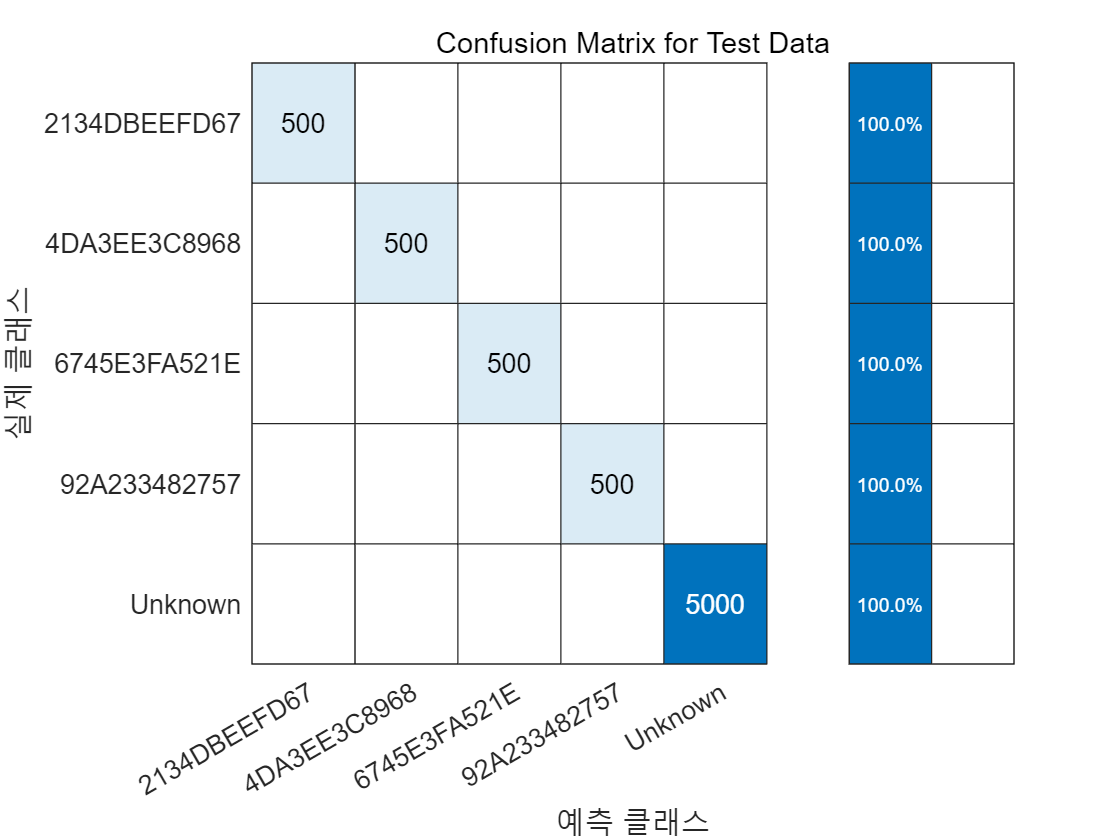

figure
cm = confusionchart(yTest, yTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';

disp('6');

6


## 7. Detect Router Impersonator

알려진 MAC 주소와 하나의 알려지지 않은 MAC 주소를 사용하여 비콘 프레임을 생성한다. 

새로운  RF 손상 및 다중 경로 채널 Set을 생성한다.

손상은 모두 새로운 것이므로 이러한 프레임의 RF 지문은 'Unknown'으로 분류되어야 한다.

알려진 MAC 주소가 있는 프레임은 Router Impersonator를 나타내고,

MAC 주소를 알 수 없는 프레임은 단순히 알 수 없는 라우터임을 나타낸다. 

framesPerRouter = 1;
knownMACAddresses = generatedMACAddresses(1:numKnownRouters);

% 이전에 정의된 범위 내에서
% 시뮬레이션 된 각각의 Radio에 랜덤 손실을 할당
for routerIdx = 1:numTotalRouters
  radioImpairments(routerIdx).PhaseNoise = rand*( phaseNoiseRange(2)-phaseNoiseRange(1) ) + phaseNoiseRange(1);
  radioImpairments(routerIdx).DCOffset = rand*( dcOffsetRange(2)-dcOffsetRange(1) ) + dcOffsetRange(1);
  radioImpairments(routerIdx).FrequencyOffset = fc/1e6*(rand*( freqOffsetRange(2)-freqOffsetRange(1) ) + freqOffsetRange(1));
end
% 정적 채널을 생성하기 위해 다중경로 채널 객체를 초기화
reset(multipathChannel)

% Run for all known routers and one unknown
for macIndex = 1:(numKnownRouters+1)
  
  beaconFrameConfig.Address2 = generatedMACAddresses(macIndex);
  
  % Generate Beacon frame bits
  beacon = wlanMACFrame(beaconFrameConfig, 'OutputFormat', 'bits');
  
  txWaveform = wlanWaveformGenerator(beacon, nonHTConfig);
  
  txWaveform = helperNormalizeFramePower(txWaveform);
  
  % Add zeros to account for channel delays
  txWaveform = [txWaveform; zeros(160,1)]; %#ok<AGROW>
  
  % Create an unseen multipath channel. In other words, create an unseen
  % RF fingerprint.
  reset(multipathChannel)
  
  frameCount= 0;
  while frameCount<framesPerRouter
    
    rxMultipath = multipathChannel(txWaveform);
    
    rxImpairment = helperRFImpairments(rxMultipath, radioImpairments(routerIdx), fs);
    
    rxSig = awgn(rxImpairment,SNR,0);
    
    % Detect the WLAN packet and return the received L-LTF signal using
    % rfFingerprintingNonHTFrontEnd object
    [payloadFull, cfgNonHT, rxNonHTData, chanEst, noiseVar, LLTF] = ...
      rxFrontEnd(rxSig);
    
    if payloadFull
      frameCount = frameCount+1;
      recBits = wlanNonHTDataRecover(rxNonHTData, chanEst, ...
        noiseVar, cfgNonHT, 'EqualizationMethod', 'ZF');
      
      % Decode and evaluate recovered bits
      mpduCfg = wlanMPDUDecode(recBits, cfgNonHT);
      
      % Separate I and Q and reshape for neural network
      LLTF= [real(LLTF), imag(LLTF)];
      LLTF = permute(reshape(LLTF,frameLength ,[] , 2, 1), [1 3 4 2]);
      
      ypred = classify(simNet, LLTF);
      
      if sum(contains(knownMACAddresses, mpduCfg.Address2)) ~= 0    % 만약 knownMACAddresses에 mpduCfg.Address2가 있으면
        if categorical(convertCharsToStrings(mpduCfg.Address2))~=ypred  % mpduCfg.Address2가 Unknown(ypred)이면 → 가장자
          disp(strcat("MAC Address ", mpduCfg.Address2," is known, fingerprint mismatch, ROUTER IMPERSONATOR DETECTED"))
        else     % mpduCfg.Address2가 Unknown(ypred)이 아니면 → 알려진 라우터
          disp(strcat("MAC Address ", mpduCfg.Address2," is known, fingerprint match"))
        end
      else       % 만약 knownMACAddresses에 mpduCfg.Address2가 없으면
        disp(strcat("MAC Address ", mpduCfg.Address2," is not recognized, unknown device")) % 그냥 알려지지 않은 라우터
      end
    end

    % Reset multipathChannel object to generate a new static channel
    reset(multipathChannel)
  end
end

MAC Address 09C551658660 is known, fingerprint mismatch, ROUTER IMPERSONATOR DETECTED
MAC Address CDECF20C29CA is known, fingerprint mismatch, ROUTER IMPERSONATOR DETECTED
MAC Address DF56A9E15405 is known, fingerprint mismatch, ROUTER IMPERSONATOR DETECTED
MAC Address EDC4537D86B1 is known, fingerprint mismatch, ROUTER IMPERSONATOR DETECTED


MAC Address AAAAAAAAAAAA is not recognized, unknown device
